close all;
clear;
clc;

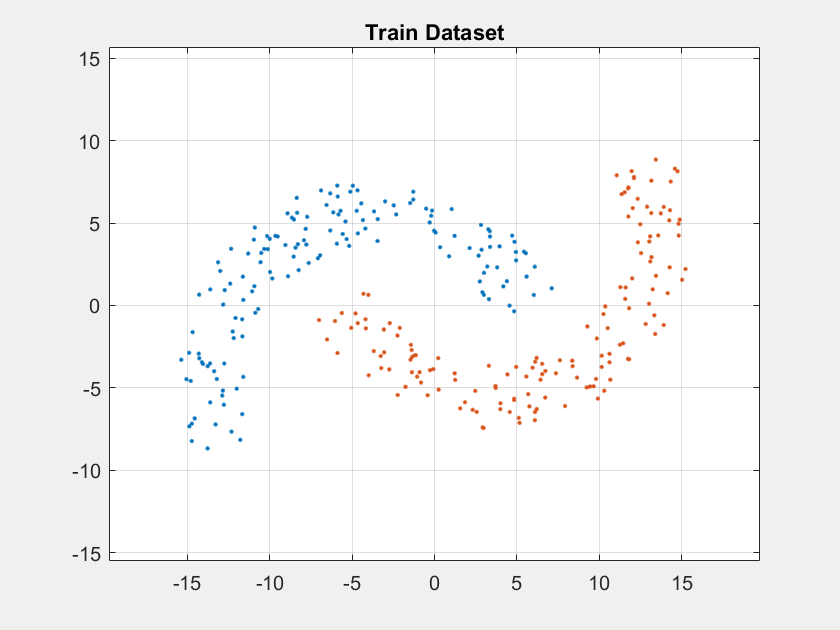

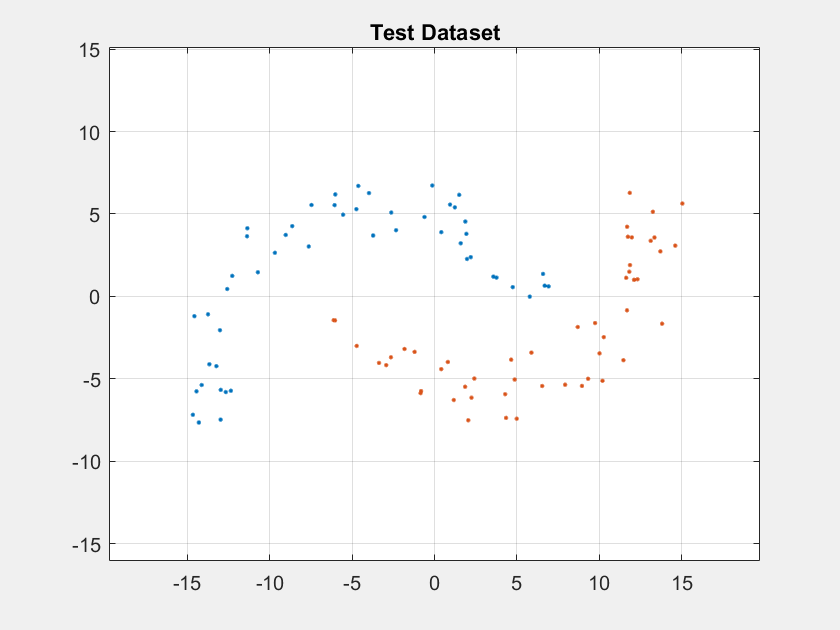

radius = 10; width = 4; theta = 25; distance = -5;
N = 400; train2total = 0.75; drawPatterns = true;

[train, test] = doubleMoonStructure( radius, width, theta, distance, ...
                                     N, train2total, drawPatterns );

N_train = train2total*N;

x_train = train(1:end, 1:2);
d_train = train(1:end, 3);

x_test = test(1:end, 1:2);
d_test = test(1:end, 3);

x_norm = dataset_normalization(x_train, "min-max scaling")

x_norm =     0.1450    0.5615
    0.0681    0.0829
    0.0356    0.5323
    0.3479    0.8226
    0.0852    0.2939
    0.6125    0.6976
    0.6387    0.5609
    0.6640    0.6509
    0.5719    0.6937
    0.4263    0.8102


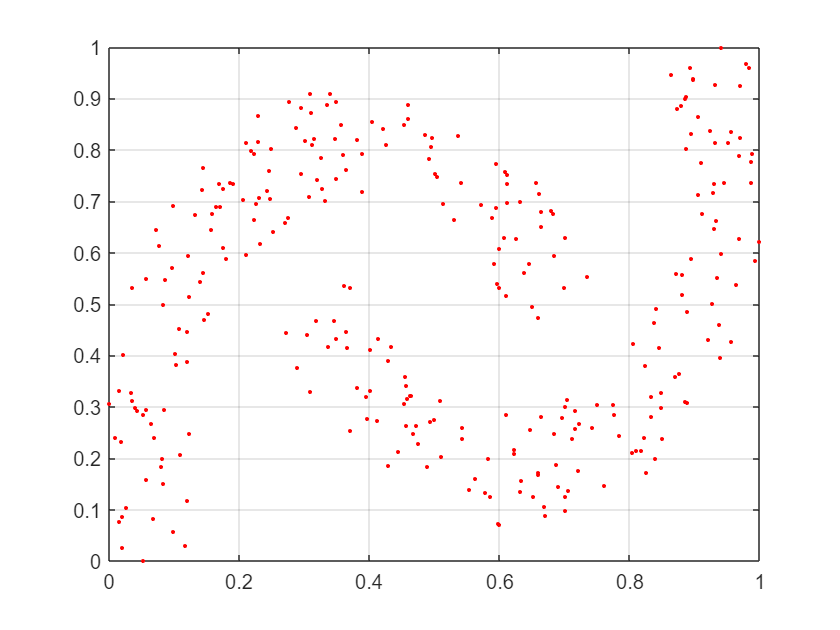


figure;
plot(x_norm(1:end, 1), x_norm(1:end, 2), 'r.');
xlim([0 1]); ylim([0 1]);
grid on;

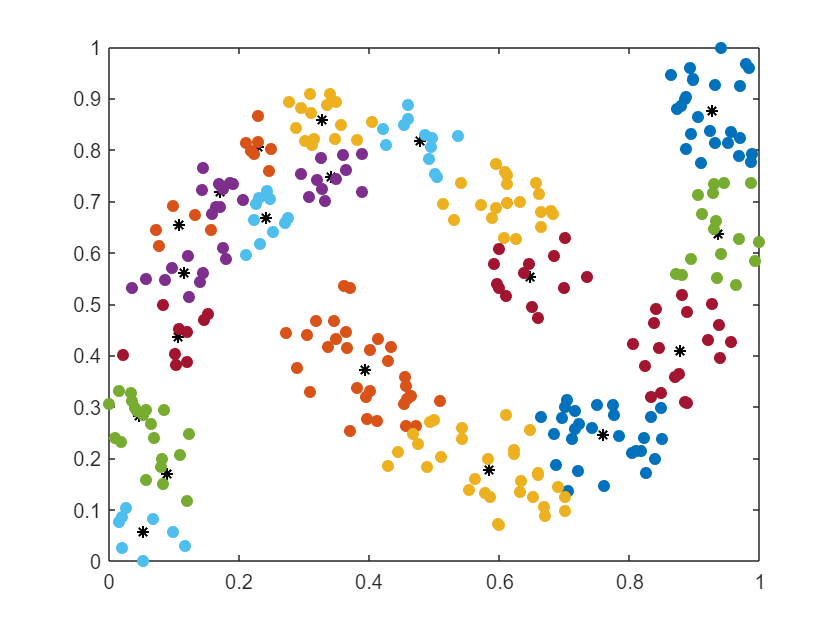

clusterCenters =     0.3943    0.3731
    0.3284    0.8592
    0.1715    0.7179
    0.0466    0.2835
    0.0527    0.0578
    0.6474    0.5533
    0.7591    0.2464
    0.1078    0.6538
    0.5848    0.1772
    0.1164    0.5614


numClusters = 20;
numIterations = 500;
[clusters, clusterCenters] = kMeansClustering(x_norm,numClusters,numIterations);

figure;
% colors = {'r','b','g','y','m','c','k'};
plot(clusterCenters(:,1),clusterCenters(:,2),'k*', LineWidth=1);
hold on;
for i = 1:numClusters
    currCluster = clusters{i};
    scatter(currCluster(:,1),currCluster(:,2),'filled');
end

% finding the practical sigma
d_max = 0;
d_temp = 0;
i_max = 0;
j_max = 0;
for i = 1:numClusters-1
    for j = 1:numClusters-i
        d_temp = norm(clusterCenters(i, 1:2) - clusterCenters(i+j, 1:2));
        if d_temp >= d_max
            d_max = d_temp;
            i_max = i;
            j_max = j;
            continue;
        end
    end 
end

sigma = d_max / sqrt(2*numClusters)

sigma = 0.1892

% RBF Implementation
% shuffling the data presented to the network
x_random = zeros(size(x_norm));
d_random = zeros(size(d_train));

j = 0;
index_shuffle = randperm(N_train);
for i = index_shuffle
    j = j + 1;
    x_random(j, :) = x_norm(i, :);
    d_random(j) = d_train(i);
end

phi = zeros([1, numClusters])';
weights = zeros([1, numClusters])';
lambda = 0.1;
P = lambda * eye(numClusters);

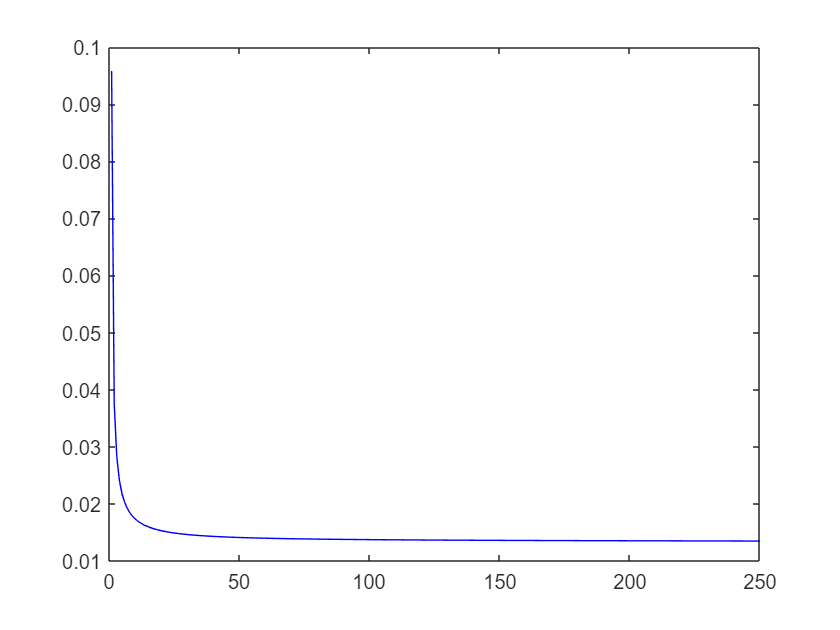

% train
maxEpoch = 250;

y = zeros(size(d_random));

ek = -1 * ones(size(d_random));   % instantaneous error signal
E = (1/2) * ek.^2;          % total instantaneous error energy
MSE = zeros([1, maxEpoch]);

for epoch = 1:maxEpoch
    i = 0;
    for x = x_random'
        for j = 1:numClusters
            phi(j) = kernel(x', clusterCenters(j, 1:2), sigma);
        end
        
        i = i + 1;
    
        P = P - ((P*(phi*phi')*P) / (1 + (phi'*P*phi)));
        g = P * phi;
        alpha = d_random(i) - weights'*phi;
        weights = weights + alpha*g;

        y(i) = weights'*phi;
        
        ek(i) = d_random(i) - y(i);
        E(i) = (1/2) * ek(i)^2;
    end
    MSE(epoch) = sum(E)/numel(E);
end

figure;
plot(1:maxEpoch, MSE, 'b');
hold on;

% test
x_test = dataset_normalization(x_test, "min-max scaling")

x_test =     0.0553    0.3893
    0.6139    0.6153
    0.3380    0.9980
    0.7267    0.5743
    0.5441    0.9605
    0.6883    0.5311
    0.5566    0.8476
    0.5601    0.6899
    0.4891    1.0000
    0.5588    0.7959



y = zeros(size(d_test));

ek_test = -1 * ones(size(d_test));   % instantaneous error signal
E_test = (1/2) * ek_test.^2;         % total instantaneous error energy

i = 0;
for x = x_test'
    for j = 1:numClusters
        phi(j) = kernel(x', clusterCenters(j, 1:2), sigma);
    end
    i = i + 1;
    y(i) = weights'*phi;
    
    ek_test(i) = d_test(i) - y(i);
    E_test(i) = (1/2) * ek_test(i)^2;
end

MSE_test = sum(E_test)/numel(E_test);
disp(MSE_test);

    0.0185



function [x_norm]=dataset_normalization(x, mode)
    %% Function for Normalization of Data
    % Two different approaches for converting features to comparable scale 
    % 1. Min-Max-Scaling makes all data fall into range [0, 1]
    % 2. Z-score conversion make center data on '0' scale data so majority falls into range [-1, 1]
    if nargin <= 1
        x_min = min(x);
        x_max = max(x);
        x_norm = (x - repmat(x_min, size(x,1), 1)) ./ repmat((x_max-x_min), size(x,1), 1);
    else
        if mode == "min-max scaling"
            x_min = min(x);
            x_max = max(x);
            x_norm = (x - repmat(x_min, size(x,1), 1)) ./ repmat((x_max-x_min), size(x,1), 1);
        else        % z-score scaling
            x_mean = mean(x);
            x_std = std(x);
            x_norm = ((x - repmat(x_mean, size(x,1), 1)) ./ (repmat(x_std, size(x,1), 1)))/2;
        end
    end
end

function [clusters, clusterCenters] = kMeansClustering(dataSet,numClusters,numIterations)    
    dataLength = size(dataSet,1);
    dataDim = size(dataSet,2);
    avgPoints = rand(numClusters,size(dataSet,2));
    for j = 1:dataDim
        avgPoints(:,j) = avgPoints(:,j)*(max(dataSet(:,j))-min(dataSet(:,j)))+min(dataSet(:,j));
    end
    
    for i = 1:numClusters
        j = ceil(rand*dataLength);
        while sum(ismember(avgPoints,dataSet(j,:),'rows')) ~= 0
            j = ceil(rand*dataLength);
        end
        avgPoints(i,:) = dataSet(j,:);
    end
    
    for iter = 1:numIterations
        dataSetAssignments = [dataSet ones(dataLength,1)];
        for i = 1:size(dataSetAssignments,1)
           minDist = norm(dataSetAssignments(i,1:dataDim).' - avgPoints(1,:).');
           minJ = 1;
           for j = 1:size(avgPoints,1)
               dist = norm(dataSetAssignments(i,1:dataDim).' - avgPoints(j,:).');
               if dist <= minDist
                   minJ = j;
                   minDist = dist;
               end
           end
           dataSetAssignments(i,dataDim+1) = minJ;
        end
        for i = 1:numClusters
            splitSet(:,:,i) = {dataSetAssignments(dataSetAssignments(:,dataDim+1)==i,1:dataDim)};
        end
        
        
        for i = 1:numClusters
            avg = mean(splitSet{i},1);
            avgPoints(i,:) = avg(1:dataDim);
        end
    end
    
    clusters = splitSet;
    clusterCenters = avgPoints;
end

function [phi] = kernel(x, center, sigma)
    phi = exp(-(norm(x - center).^2) / (2*sigma^2));
end